# **Estimate Model-Based Volatility**

One disadvantage of using the exponentially weighted moving average for volatility estimation is that it does not provide volatility forecasts. However, you can use a model-based approach to create volatility forecasts. This example uses [arima](docid:econ_ug.bs6v6be) and [garch](docid:econ_ug.buochls) time-series models.

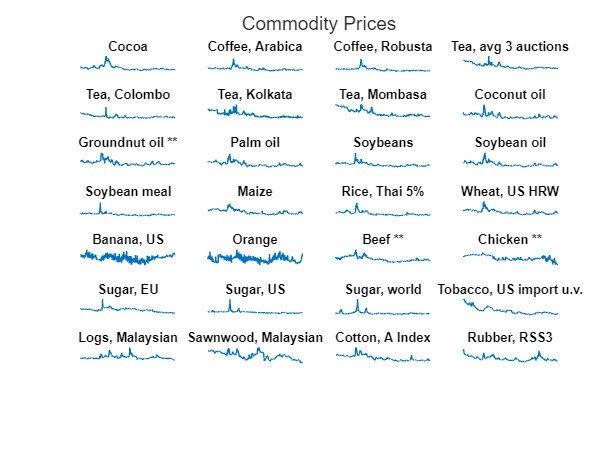

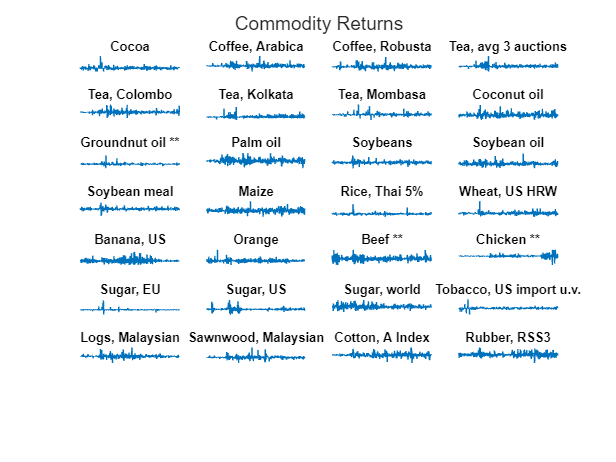

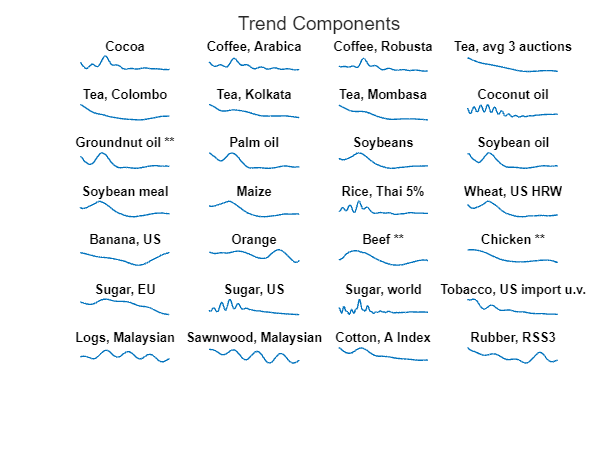

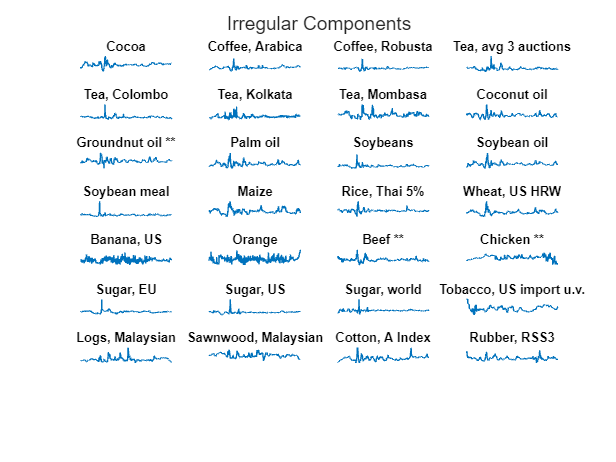

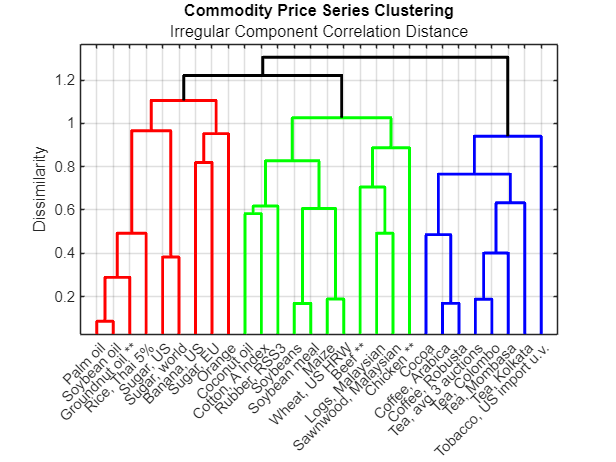

            Commodity            Group
    _________________________    _____

    "Coconut oil"                  1  
    "Soybeans"                     1  
    "Soybean meal"                 1  
    "Maize"                        1  
    "Wheat, US HRW"                1  
    "Beef **"                      1  
    "Chicken **"                   1  
    "Logs, Malaysian"              1  
    "Sawnwood, Malaysian"          1  
    "Cotton, A Index"              1  
    "Rubber, RSS3"                 1  
    "Groundnut oil **"             2  
    "Palm oil"                     2  
    "Soybean oil"                  2  
    "Rice, Thai 5%"                2  
    "Banana, US"                   2  
    "Orange"                       2  
    "Sugar, EU"                    2  
    "Sugar, US"                    2  
    "Sugar, world"                 2  
    "Cocoa"                        3  
    "Coffee, Arabica"             

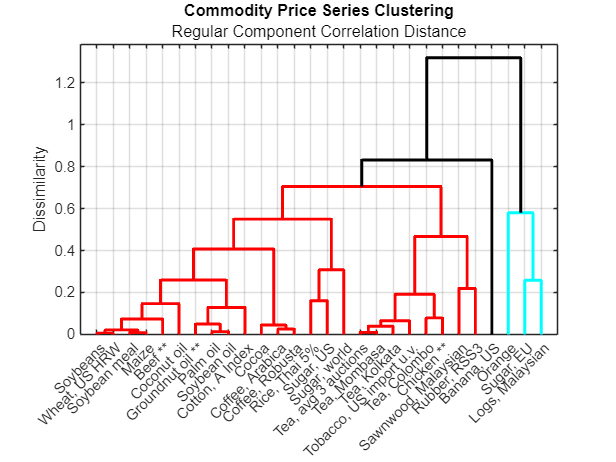

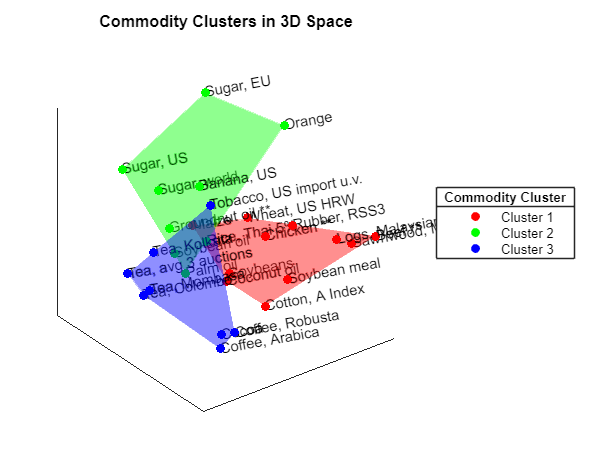

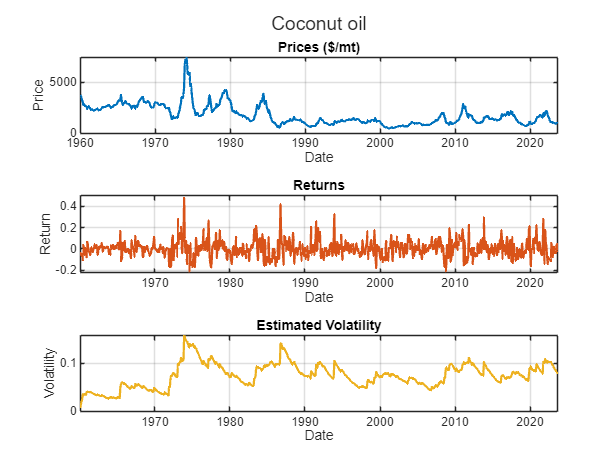

x3_EstimateNonparametricVolatility

### Compute Principal Components of Inferred Volatility

First, use [normalize](docid:matlab_ref.mw_3d2d97f9-e35e-4f03-9aac-6ffe49f1400a) on the volatility series and store the mean and standard deviation for later use.

[normalizedVolatility, mu, sigma] = normalize( InferredVolatility.Variables, "zscore" );

Next, compute the principal components by using [pca](docid:stats_ug.bth9ibe).

[coeffs, scores, eigVals] = pca( normalizedVolatility );

Visualize the eigenvalues of the covariance matrix of the normalized volatilities.

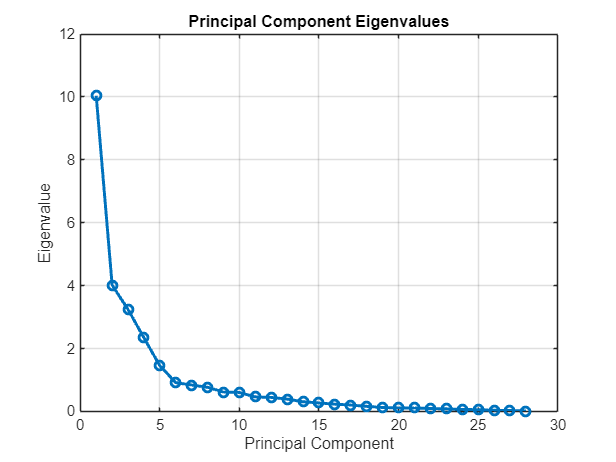

figure
plot( eigVals, "o-", "LineWidth", 2 )
xlabel( "Principal Component" )
ylabel( "Eigenvalue" )
title( "Principal Component Eigenvalues" )
grid( "on" )

You can see that most of the variance in the data is captured by the first few principal components.

Visualize the first two principal components.

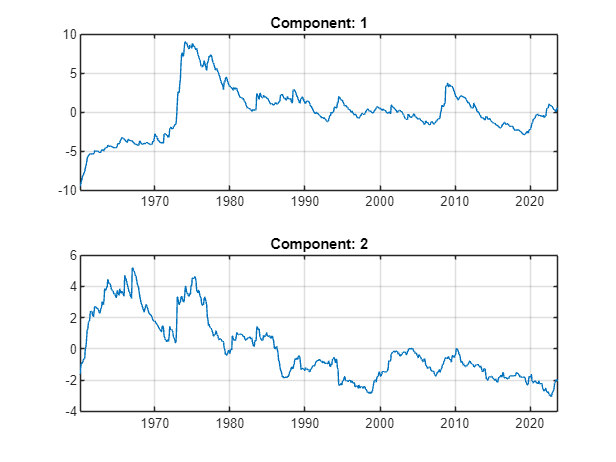

numComponents = 2;

figure
tiledlayout( "flow" )

for k = 1:numComponents
    nexttile
    plot( InferredVolatility.Date, scores(:, k ) )
    title( "Component: " + k )
    grid( "on" )
end

### Model Principal Components

Rather than creating many separate time-series models for each soft commodity, you can take an efficient approach by building models for only the first few principal components. You can then back-transform forecasts from these models into the original domain. 

Create and fit an [arima](docid:econ_ug.bs6v6be) time-series model for the first principal component.

firstComponent = scores(:, 1);

firstComponentModel = arima( "ARLags", 1, ...
    "MALags", 1, ...
    "Distribution", "t", ...
    "Variance", garch( 1, 1 ) );
firstComponentModel = estimate( firstComponentModel, firstComponent );

 
    ARIMA(1,0,1) Model (t Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.063238       0.006214       -10.177      2.5191e-24
    AR{1}         0.98215      0.0019302        508.82               0
    MA{1}         0.15671       0.031714        4.9412      7.7631e-07
    DoF            2.5091        0.24115        10.405      2.3521e-25

 
 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    _

Create and fit an [arima](docid:econ_ug.bs6v6be) time-series model for the second principal component.

secondComponent = scores(:, 2);
secondComponentModel = arima("ARLags", 1, ...
    "MALags", 1, ...
    "Distribution", "t", ...
    "Variance", garch( "ARCHLags", 1, ...
    "Constant", 0.01, ...
    "GARCHLags", 1 ) );
secondComponentModel = estimate( secondComponentModel, secondComponent );

 
    ARIMA(1,0,1) Model (t Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    -0.025173      0.0043829       -5.7433       9.2841e-09
    AR{1}         0.98224       0.002459        399.45                0
    MA{1}        0.077561       0.025207         3.077        0.0020913
    DoF            2.1625       0.086605         24.97      1.3065e-137

 
 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    <s

### Create Simulated Component Values from Fitted Models

Use [simulate](docid:econ_ug.bs678hw) to create the simulated component values from the fitted models.

numForecastSteps = 60;
simFirstComponent = simulate( firstComponentModel, numForecastSteps, "Y0", firstComponent );
simSecondComponent = simulate( secondComponentModel, numForecastSteps, "Y0", secondComponent );
simComponents = [simFirstComponent, simSecondComponent];

### Back-Transform Simulated Component Values

Transform the simulation results in the principal component domain back to the original volatility domain, adjusting for the normalization step performed in Compute Principal Components of Inferred Volatility. Since you have modeled only the first two principal components, this transformation is an approximation to the volatility. Modeling more of the principal components would lead to a more accurate volatility approximation at the cost of more modeling, simulation, and execution time.

approxVolatility = mu + sigma .* (simComponents * coeffs(:, 1:2).');
approxVolatility = [InferredVolatility{end, :}; approxVolatility];

Convert the volatility approximations to the timetable format.

simDates = InferredVolatility.Date(end) + calmonths(0:numForecastSteps).';
approxVolatility = array2timetable( approxVolatility, ...
    "RowTimes", simDates, "VariableNames", commodityNames );
approxVolatility.Properties.DimensionNames(1) = "Date";

### Visualize Volatility Simulation Results

In the **Model-Based Volatility Simulation** plot, the blue line indicates historical data and the red line indicates the simulated volatility moving into the future.

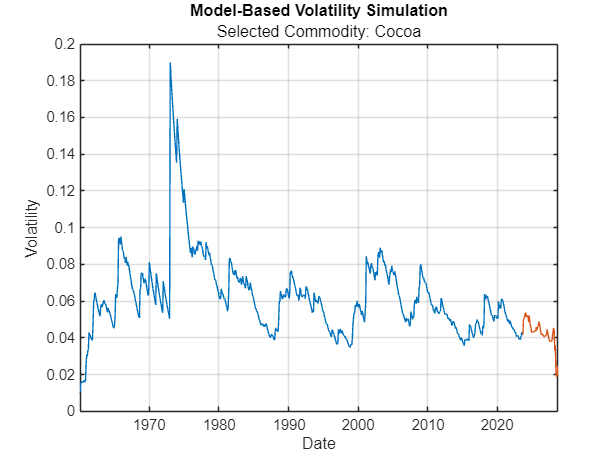

selectedCommodity = commodityNames(1);

figure
plot( InferredVolatility.Date, InferredVolatility.(selectedCommodity) )
hold on
plot( approxVolatility.Date, approxVolatility.(selectedCommodity) )
xlabel( "Date" )
ylabel( "Volatility" )
title( "Model-Based Volatility Simulation" )
subtitle( "Selected Commodity: " + selectedCommodity )
grid on

## References

[1] The World Bank: Commodity Monthly Prices, located at: [https://www.worldbank.org/en/research/commodity-markets](https://www.worldbank.org/en/research/commodity-markets) and licensed under [CC BY 4.0 Deed | Attribution 4.0 International | Creative Commons](https://creativecommons.org/licenses/by/4.0/).

[2] U.S. Bureau of Labor Statistics, Consumer Price Index for All Urban Consumers: Purchasing Power of the Consumer Dollar in U.S. City Average [CUUR0000SA0R]. Available at [https://beta.bls.gov/dataViewer/view/timeseries/CUUR0000SA0R](https://beta.bls.gov/dataViewer/view/timeseries/CUUR0000SA0R). Data provided by the U.S. Bureau of Labor Statistics through the BLS Data Viewer at BLS.gov. BLS.gov cannot vouch for the data or analyses derived from these data after the data have been retrieved from BLS.gov.